% Modelling ML

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);

% ********** 1) Baseline Models **********

% 1a) Baseline Decision Tree
disp('Baseline Decision Tree')
% Train
dt_base = fitctree(X_train, y_train);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

% 1b) Baseline Random Forest
disp('Baseline Random Forest')
% Train
rf_base = TreeBagger(300, X_train, y_train);
% Evaluate
test_model(rf_base, X_test, y_test)

% ********** 2) Tuned Models **********

% Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train)
c = cvpartition(nrow,'KFold', 10)

% 2a) Optimized Tree with CV
% Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
prune = optimizableVariable('prune', {'on','off'},'Type','categorical'); % default: 'on'
PruneCriterion = optimizableVariable('PruneCriterion',  {'error', 'impurity'}, 'Type','categorical'); % default: 'error'
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1
ParamsDT= [prior, prune, PruneCriterion, MaxNumSplit, MinLeafSize];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_dt_cv(params,X_train,y_train, c), ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

% Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'prior', char(z.prior), 'prune', char(z.prune), ...
    'PruneCriterion', char(z.PruneCriterion), 'MaxNumSplits', z.MaxNumSplit, 'MinLeafSize', z.MinLeafSize);

% Evaluate
test_model(dt_best, X_test, y_test)

|==============================================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |        prune | PruneCriteri-|  MaxNumSplit |  MinLeafSize |     NumTrees | NumPredictor-| InBagFraction| SampleWithRe-|
|      | result |             | runtime     | (observed)  | (estim.)    |              |              | on           |              |              |              | sToSample    |              | placement    |
|==============================================================================================================================================================================================================|
|    1 | Best   |           1 |      5.3402 |           1 |           1 |    empirical |           on |        error |           12 |           24 |          859 | 

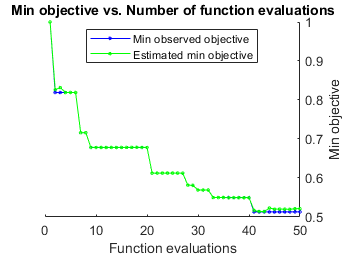


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 130.2754 seconds
Total objective function evaluation time: 103.5082

Best observed feasible point:
     prior     prune    PruneCriterion    MaxNumSplit    MinLeafSize    NumTrees    NumPredictorsToSample    InBagFraction    SampleWithReplacement
    _______    _____    ______________    ___________    ___________    ________    _____________________    _____________    _____________________

    uniform     on          error             29              1            99                14                 0.25602     

% 2b) Optimized Random Forest with CV
% Tree vars
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1
% Forest vars
NumTrees = optimizableVariable('NumTrees', [10,1000],'Type','integer');
NumPredictorsToSample = optimizableVariable('NumPredictorsToSample',[1,17],'Type','integer');  % default: sqrt(# features)
InBagFraction = optimizableVariable('InBagFraction', [0.01,1.0],'Type','real');  % default: 1
SampleWithReplacement = optimizableVariable('SampleWithReplacement', {'on','off'},'Type','categorical'); % default: 'empirical'
% Add to tree parameters
ParamsRF = [ParamsDT, NumTrees, NumPredictorsToSample, InBagFraction, SampleWithReplacement];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)fb_loss_rf_cv(params,X_train,y_train), ParamsRF,...
    'AcquisitionFunctionName','expected-improvement-plus', 'ExplorationRatio', 0.2, 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

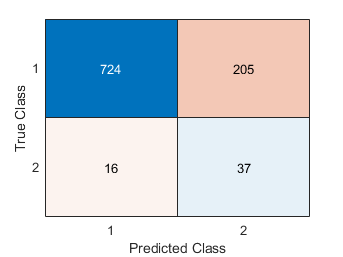

accuracy = 0.7749

precision = 0.1529

recall = 0.6981

specificity = 0.7793

fb = 0.2508


% Train optimized model on entire data set
z = bestPoint(results);
rf_best = TreeBagger(z.NumTrees, X_train, y_train, 'prior', char(z.prior),...
    'MaxNumSplits', z.MaxNumSplit, 'MinLeafSize', z.MinLeafSize, ...
    'NumPredictorsToSample', z.NumPredictorsToSample, 'InBagFraction', z.InBagFraction, ...
    'SampleWithReplacement', char(z.SampleWithReplacement));

% Evaluate
test_model(dt_best, X_test, y_test)

function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    % Evaluation metrics for binary classification
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);
    %confusionchart(cmat);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end

% Test model without CV folds
function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    if iscell(y_pred) % RF outputs cell and must be converted
        y_pred = str2num(cell2mat(y_pred));
    end
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    confusionchart(cmat);
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, ...
             'prior', char(params.prior), 'prune', char(params.prune), ...
             'PruneCriterion', char(params.PruneCriterion), ...
             'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% RF function CV
function fb = fb_loss_rf_cv(params, X_train, y_train)
        % Train model (TreeBagger has no CV parameter)
        crossval('mcr',X_train,y_train,'Partition',cvp);
        
        model = TreeBagger(params.NumTrees, X_train, y_train,...
             'prior', char(params.prior), ...% Tree parameters
             'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeafSize, ...% Forest parameters
             'NumPredictorsToSample', params.NumPredictorsToSample, 'InBagFraction', params.InBagFraction, ...
             'SampleWithReplacement', char(params.SampleWithReplacement));
            
        % Calculate F-beta score
        y_pred = predict(model, X_train);
        y_pred = str2num(cell2mat(y_pred));  % RF outputs cell and must be converted
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end
%#ok<*ASGLU,*NOPRT> 